# **Analyzing Neural Time Series Data**

*Theory and Practice: Mike X Cohen*

*Presented by: Armin Toghi*

*IDS Executive Member of Signal and Neuroimaging Department*

[armintoghi85@gmail.com](http://armintoghi85@gmail.com)

### STFT

The short-time FFT is an alternative method for extracting time-frequency power and phase information. The short-time FFT is a simple extension of the Fourier transform that addresses the two main limitations of the Fourier transform for EEG time-frequency analyses that were identified in chapter 11: the Fourier transform obscures time-varying changes in the frequency structure of the data, and the Fourier transform assumes that the data are stationary for the duration of the time series.

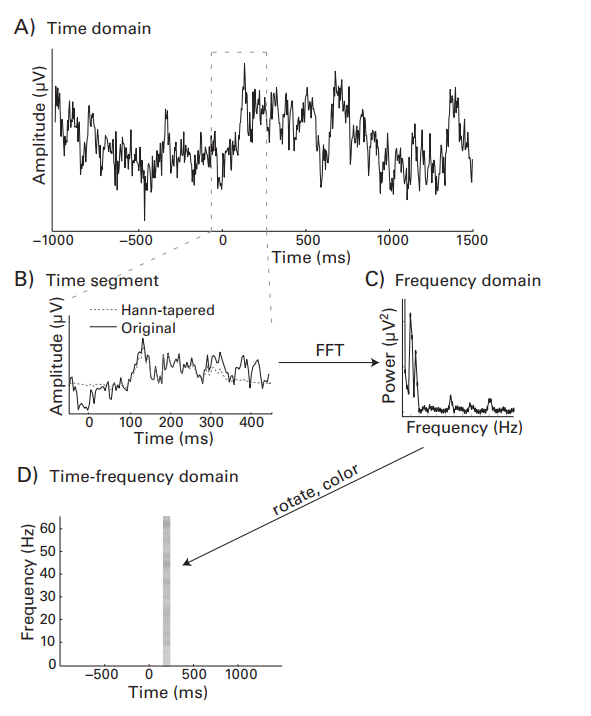

### **How the Short-Time FFT Works**  

use the FFT to extract the frequency structure of brief segments of data (time windows) rather than the entire time series (Makeig 1993; Welch 1967).  

Before computing the Fourier transform of each time segment, you **should taper the data in that segment.** This will attenuate the amplitude of the data at the beginning and at the end of the time segment, which is important for preventing edge artifacts from contaminating the time-frequency results.   

*Note: The downside of tapering is that it attenuates valid EEG signal, but this effect can be mitigated by using temporally overlapping segments.   *

There are several possible tapers to use, including Hann, Hamming, and Gaussian. The Hann window is advantageous because it tapers the data fully to zero at the beginning and end of the time segment.  The Gaussian can be made to taper to zero, but the window becomes fairly narrow, which may excessively taper the data. The Hamming window does not fully taper the data to zero.

load sampleEEGdata.mat
timewin = 500; % in ms
timewinidx = round(timewin/(1000/EEG.srate));

% create hamming
hamming_win = .54 - .46*cos(2*pi*(0:timewinidx-1)/(timewinidx-1));
hann_win    = .5*(1-cos(2*pi*(0:timewinidx-1)/(timewinidx-1)));

% create gaussian
gaus_win = exp(-.5*(2.5*(-timewinidx/2:timewinidx/2-1)/(timewinidx/2)).^2);

% plot together
figure
plot(hann_win)
hold on
plot(hamming_win,'r')
plot(gaus_win,'k')
legend({'Hann';'Hamming';'Gaussian'})
set(gca,'xlim',[-5 timewinidx+5],'ylim',[-.1 1.1],'ytick',0:.2:1)

load sampleEEGdata

timewin = 500; % in ms

% convert ms to idx
timewinidx = round(timewin/(1000/EEG.srate));


% create hann taper function
hann_win = .5*(1-cos(2*pi*(0:timewinidx-1)/(timewinidx-1)));

% detrend data (useful to attentuate super-low frequency artifacts in FFT
% from sampled data)
d = detrend(EEG.data(20,:,16));

figure
subplot(311)
plot(EEG.times,d)
title('One trial of data')

[junk,stime] = min(abs(EEG.times--50));

subplot(323)
plot(EEG.times(stime:stime+timewinidx-1),d(stime:stime+timewinidx-1))
hold on
plot(EEG.times(stime:stime+timewinidx-1),d(stime:stime+timewinidx-1).*hann_win,'r')
set(gca,'xlim',[-50 -50+timewin])
title('One short-time window of data, windowed')

dfft = fft(d(stime:stime+timewinidx-1).*hann_win);
f    = linspace(0,EEG.srate/2,floor(length(hann_win)/2)+1); % frequencies of FFT
subplot(313)
plot(f(2:end),abs(dfft(2:floor(length(hann_win)/2)+1)).^2,'.-');
title('power spectrum from that time window')
set(gca,'xlim',[1 128],'ylim',[-1000 25000],'xtick',0:10:EEG.srate/2)


% create TF matrix and input column of data at selected time point
tf = zeros(floor(length(hann_win)/2),EEG.pnts);
tf(:,stime+timewinidx/2-10:stime+timewinidx/2+10) = repmat(abs(dfft(2:floor(length(hann_win)/2)+1)')*2,1,21);

figure
imagesc(EEG.times,f,log10(tf+1))
set(gca,'clim',[-1 1]*4)

### **Time Segment Lengths and Overlap**  

The length of the time segment offers the much-discussed trade-off between temporal and frequency precision and resolution: shorter time segments provide better temporal precision at the expense of frequency precision and resolution, whereas longer time segments provide better frequency precision and resolution at the expense of decreased temporal precision.

Remember from chapter 11 that the frequency resolution of a Fourier transform is defined by the number of points in the time series. Therefore, the larger the time segment, the more frequencies can be extracted, and thus the greater the frequency resolution. The temporal resolution is always defined by the data sampling rate and thus does not depend on the length of the time segment.

**The choice of time segment length is also related to the lowest frequency you want to analyze.** The segment must be long enough to capture at least one cycle of the lowest frequency, and preferably more than one cycle to increase signal-to-noise ratio. Thus, if you want to analyze 3-Hz activity, the window must be at least 333 ms long, and preferably 667 ms or 999 ms to capture two or three cycles (or any length; time segment lengths need not be integer multiples of cycle durations).

To adapt the short-time FFT method such that the trade-off between temporal precision and frequency precision changes as a function of frequency, you can change the time segment length as a function of frequency: lower frequencies can have longer time segments while higher frequencies can have shorter time segments.

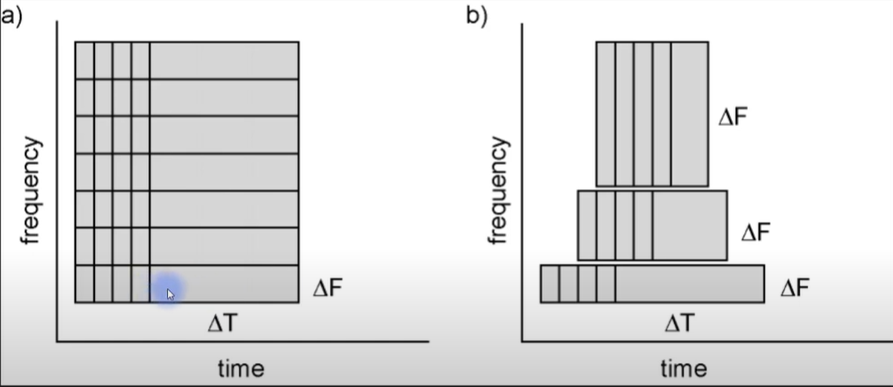

### Overlap between segments

A second parameter of the short-time FFT is the amount of overlap between successive time segments. Having temporal overlap is useful for three reasons: it **improves the temporal precision**, it** mitigates the loss of signal due to tapering**, and** it smoothes the time-frequency plots**, thus facilitating **visual inspection of the time courses of activities**. Although there are no rules or strict guidelines for how much overlap to use, values between 50% and 90% of the length of the segment are acceptable.

### **Power and Phase**  in SFT

Similar to complex wavelet convolution and the filter-Hilbert method, the short-time FFT method provides information about power and phase. Power values can be used and interpreted in the same way as power values from wavelet convolution and filter-Hilbert. Phase values from the short-time FFT, however, are not the same as the phase values from wavelet convolution or filter-Hilbert. Whereas the phase-angle–time series from wavelet convolution or filter-Hilbert is an estimate of the instantaneous phase value at each time point, the phase value from the short-time FFT method is the phase parameter of the sine wave at each frequency, in other words, the *y*-axis intercept of the sine wave at zero on the *x*-axis.

load sampleEEGdata.mat
chan2use = 'o1';
frequency2plot = 10;  % in Hz
timewin        = 400; % in ms, for stFFT
times2save     = -300:50:1000; % in ms
timewinidx = round(timewin/(1000/EEG.srate));
% create hann taper
hann_win = .5*(1-cos(2*pi*(0:timewinidx-1)/(timewinidx-1)));
times2saveidx = zeros(size(times2save));
for i=1:length(times2save)
    [junk,times2saveidx(i)]=min(abs(EEG.times-times2save(i)));
end
% define frequencies
frex = linspace(0,EEG.srate/2,floor(timewinidx/2)+1);

[junk,freq2plotidx]=min(abs(frex-frequency2plot));

% initialize ITPC output matrix
itpc = zeros(length(frex),length(times2save));

% loop over time points and perform FFT
for timepointi=1:length(times2save)
    
    % extract time series data for this center time point
    % (yes, yes, it's a long line of code. Perhaps you can understand it
    % better by breaking it up into several lines to separately identify
    % channel index and time window?)
    tempdat = squeeze(EEG.data(strcmpi(chan2use,{EEG.chanlocs.labels}),times2saveidx(timepointi)-floor(timewinidx/2):times2saveidx(timepointi)+floor(timewinidx/2)-mod(timewinidx+1,2),:));
    
    % taper data (Note the difference between using repmat here and bsxfun
    % earlier in the code.)
    taperdat = tempdat.*repmat(hann_win',1,EEG.trials);
    
    fdat = fft(taperdat,[],1)/timewinidx; % 3rd input is to make sure fft is over time
    itpc(:,timepointi) = abs(mean(exp(1i*angle(fdat(1:floor(timewinidx/2)+1,:))),2)); % average over trials
end

figure
contourf(times2save,frex,itpc,40,'linecolor','none')
set(gca,'clim',[0 .5],'xlim',[-200 1000])
title([ 'ITPC at sensor ' chan2use ])

figure
plot(times2save,mean(itpc(freq2plotidx-2:freq2plotidx+2,:),1))
title([ 'ITPC at sensor ' chan2use ', ' num2str(frequency2plot) ' Hz' ])
set(gca,'xlim',[-200 1000])

### **Describing This Analysis in Your Methods Section**

If you use the short-time FFT approach to analyze your data, make sure the Methods section in your paper clearly states the relevant parameters so that someone else could replicate your analyses. The relevant parameters include the overlap between successive time segments, how many frequencies were extracted (that is, the requested frequencies), whether the time segment length changed as a function of requested frequency, whether neighboring frequencies were averaged together to increase signal-to-noise ratio, and finally, which function was used to taper the data. If you used a software package or toolbox such as eeglab, write which functions were used, and any parameters that were changed from their default settings.

# Comparing wavelet, filter-Hilbert, and STFFT

[https://www.youtube.com/watch?v=6x3iFs_j5j8](https://www.youtube.com/watch?v=6x3iFs_j5j8)

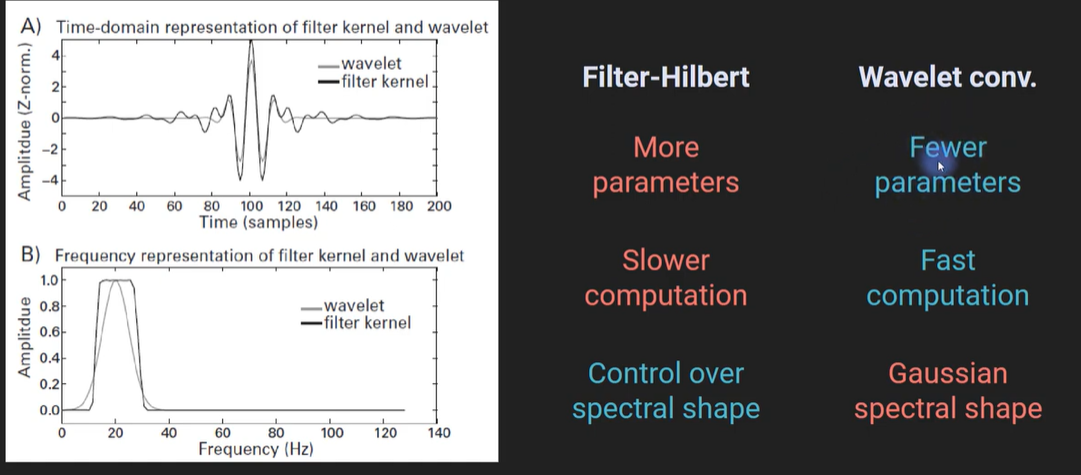

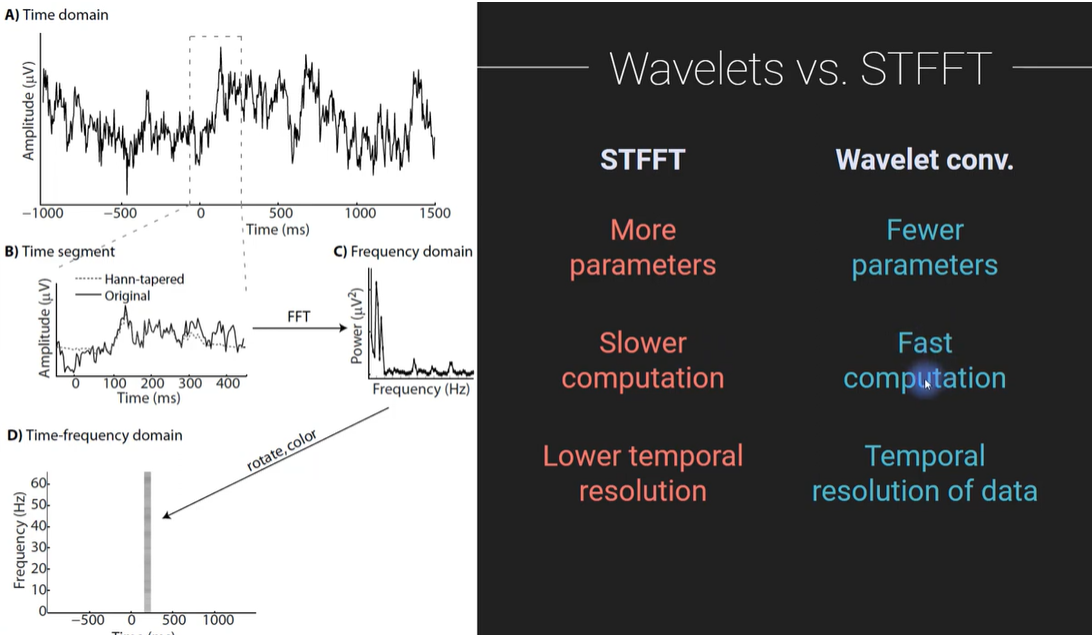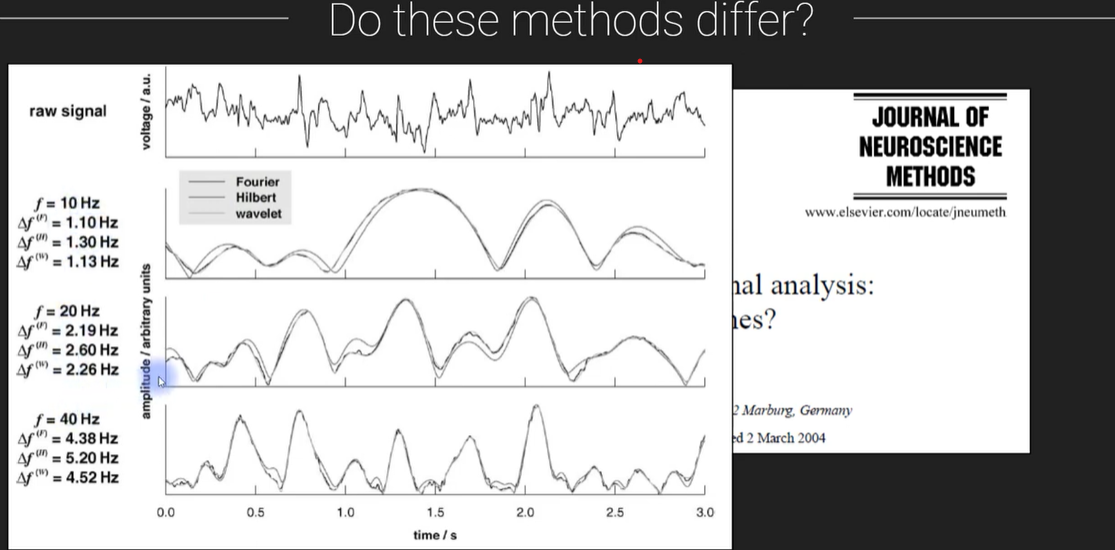

### Exercise:

1. Compute the short-time FFT at each electrode and make topographical maps of thetaband (around 6 Hz) power and alpha-band (around 10 Hz) power at 150 ms and 700 ms.  

2. Select one electrode and one frequency and compute power over time at that electrode and that frequency using complex wavelet convolution, filter-Hilbert, and the short-time FFT. Plot the results of these three time-frequency decomposition methods in different subplots of one figure. Note that the scaling might be different because no baseline normalization has been applied. How visually similar are the results from these three methods? If the results from the three methods are different, how are they different, and what parameters do you think you could change in the three methods to make the results look more or less similar ?  

3. The multitaper approach is an extension of the short-time FFT method that is designed to increase the signal-to-noise ratio of the frequency representation by applying several tapers that have slightly different temporal (and thus spectral) characteristics (Mitra and Pesaran 1999; Thomson 1982). The multitaper method is particularly useful for situations of low signal-to-noise ratio, such as higher-frequency activity or single-trial estimates of power.  First read chapter 16 of the Cohen book. Then try to describe in detail how multitaper works and if you have a simple implementation from it, you would gain a bonus!